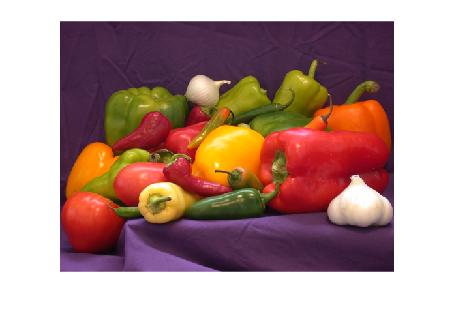

clear variables

% a)
im = imread('peppers.png');
figure,imshow(im)

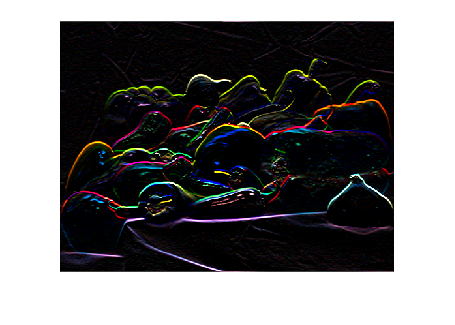

% b)
h1 = [1 2 1; 0 0 0; -1 -2 -1];
imf = imfilter(im, h1,'conv','circular');
figure,imshow(imf)

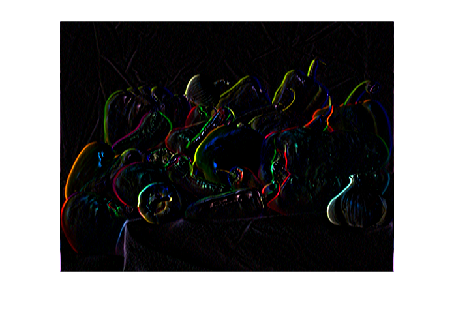

% c)
h2 = transpose(fspecial('prewitt'));
imf = imfilter(im, h2,'conv','circular');
figure,imshow(imf)

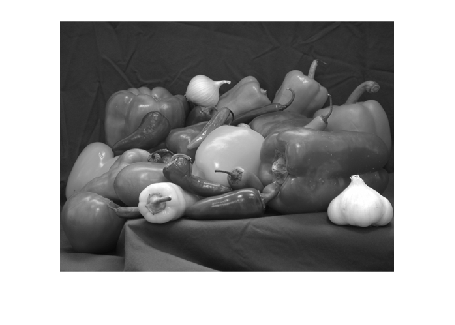

% d)
M = size(im,1); N = size(im,2);
[H1,f11,f21] = freqz2(h1,[M, N]);
[H2,f12,f22] = freqz2(h2,[M, N]);
% e)
if (ndims(im)==3) 
 im = rgb2gray(im);
end
F = fftshift(fft2(double(im)));
figure, imshow(im);

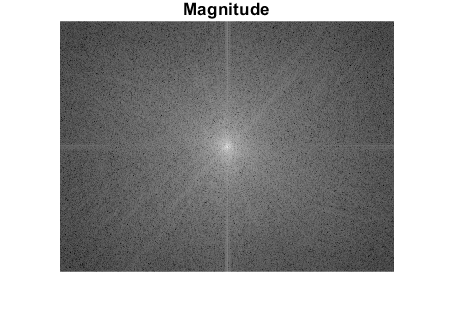

figure, imshow(log(abs(F)),[]); title('Magnitude')

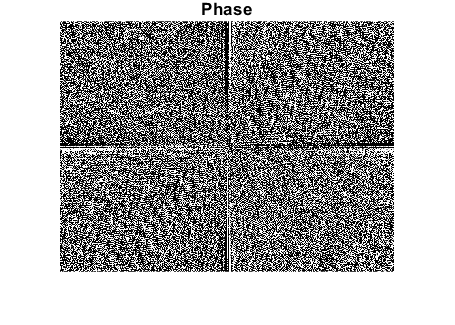

figure, imshow(angle(F)); title('Phase')

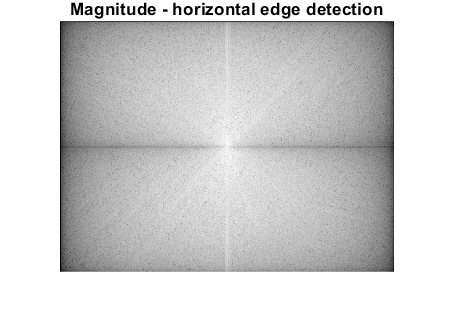

% f)
G1 = H1.*F;
figure, imshow(log(abs(G1)),[]); title('Magnitude - horizontal edge detection')

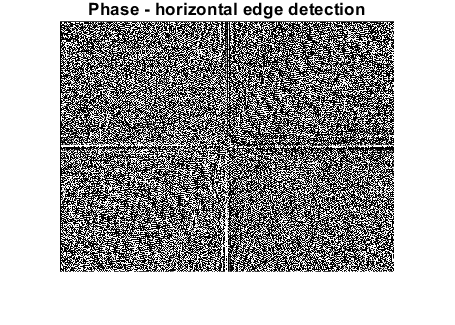

figure, imshow(angle(G1)); title('Phase - horizontal edge detection')

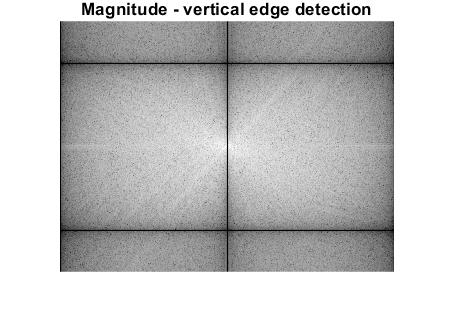

G2 = H2.*F;
figure, imshow(log(abs(G2)),[]); title('Magnitude - vertical edge detection')

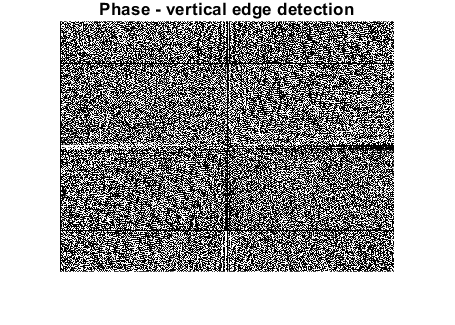

figure, imshow(angle(G2)); title('Phase - vertical edge detection')

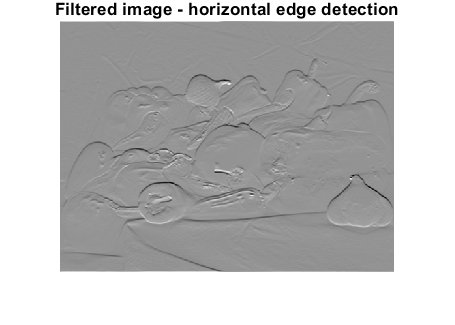

% g)
imgf1 = real(ifft2(ifftshift(double(G1))));
figure, imshow(imgf1,[ ]); title('Filtered image - horizontal edge detection')

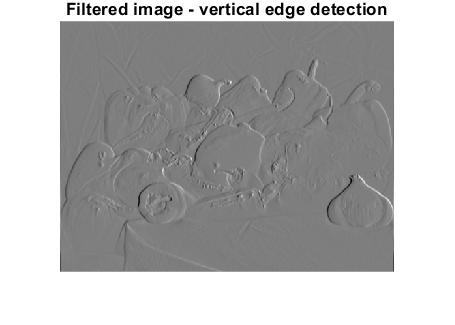

imgf2 = real(ifft2(ifftshift(double(G2))));
figure, imshow(imgf2,[ ]); title('Filtered image - vertical edge detection')

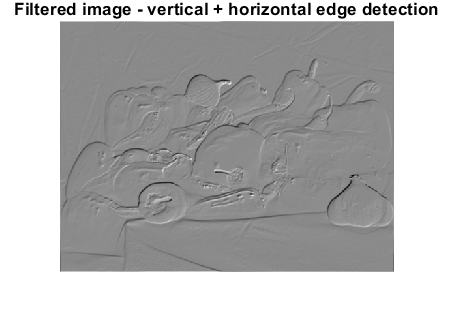

% h)
imgf = (imgf1 + imgf2)/2;
% i)
figure, imshow(imgf,[ ]); title('Filtered image - vertical + horizontal edge detection')